# Hausübung 3

Aufgabe 1

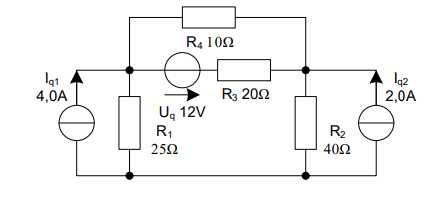

## Überlagerung nach Helmholtz

Iq1=4; Iq2=2; Uq=12; R1=25; R2=40; R3=20; R4=10;
% nur Iq1 aktiv
R34_1 = 1/(1/R3+1/R4);
R234_1 = R2+R34_1;
R1234_1 = 1/(1/R1+1/R234_1);
I2_1 = Iq1*(R1234_1/R234_1)

I2_1 = 1.3953

I1_1 = Iq1*(R1234_1/R1)

I1_1 = 2.6047

I3_1 = I2_1*(R34_1/R3)

I3_1 = 0.4651

I4_1 = I2_1*(R34_1/R4)

I4_1 = 0.9302


% nur Iq2 aktiv
R34_2 = R34_1;
R134_2 = R34_2+R1;
R1234_2 = 1/(1/R2+1/R134_2);
I1_2 = Iq2*(R1234_2/R134_2)

I1_2 = 1.1163

I2_2 = Iq2*(R1234_2/R2)

I2_2 = 0.8837

I3_2 = -(I1_2*(R34_2/R3))

I3_2 = -0.3721

I4_2 = -(I1_2*(R34_2/R4))

I4_2 = -0.7442


% nur Uq aktiv
R12_3 = R1+R2;
R124_3= 1/(1/R4+1/R12_3);
R1234_4 = R124_3+R3;
I3_3 = -Uq/R1234_4

I3_3 = -0.4186

I4_3 = -I3_3*(R124_3/R4)

I4_3 = 0.3628

I1_3 = -I3_3*(R124_3/R12_3)

I1_3 = 0.0558

I2_3 = -I1_3

I2_3 = -0.0558


% Berechnung der Ströme
I1=I1_1+I1_2+I1_3

I1 = 3.7767

I2=I2_1+I2_2+I2_3

I2 = 2.2233

I3=I3_1+I3_2+I3_3

I3 = -0.3256

I4=I4_1+I4_2+I4_3

I4 = 0.5488


%Berechnung der Spannungen
U1 = R1*I1

U1 = 94.4186

U2 = R2*I2

U2 = 88.9302

U3 = R3*I3

U3 = -6.5116

U4 = R4*I4

U4 = 5.4884

## Maschen- und Knotengleichungen

clear
Iq1=4; Iq2=2; Uq=12; R1=25; R2=40; R3=20; R4=10;

% GLG Vektor
AA = [ R1    -R2     -R3     0               
       0      0     -R3    R4
       1      0      1      1 
       0      1     -1     -1]

A =     25   -40   -20     0
     0     0   -20    10
     1     0     1     1
     0     1    -1    -1


% Quellenvektor
QQ = [Uq;Uq;Iq1;Iq2]

L =     12
    12
     4
     2


% Stromvektor I(n)
II = AA\QQ

I =     3.7767
    2.2233
   -0.3256
    0.5488



% Berechnung der Spannungen
U1 = R1*II(1)

U1 = 94.4186

U2 = R2*II(2)

U2 = 88.9302

U3 = R3*II(3)

U3 = -6.5116

U4 = R4*II(4)

U4 = 5.4884

## Maschenstromverfahren

clear
Iq1=4; Iq2=2; Uq=12; R1=25; R2=40; R3=20; R4=10;
Uq1=Iq1*R1; Uq2=Iq2*R2;

RR = [R1+R3+R2     -R3
        -R3       R3+R4 ]

RR =     85   -20
   -20    30



UU = [Uq1+-Uq-Uq2; Uq]

UU =      8
    12



IIM = RR\UU

IIM =     0.2233
    0.5488



I4 = IIM(2)

I4 = 0.5488

I3 = IIM(1)-IIM(2)

I3 = -0.3256

I1 = Iq1-IIM(1)

I1 = 3.7767

I2 = Iq2+IIM(1)

I2 = 2.2233


U1 = R1*I1

U1 = 94.4186

U2 = R2*I2

U2 = 88.9302

U3 = R3*I3

U3 = -6.5116

U4 = R4*I4

U4 = 5.4884

## Knotenpotentialverfahren

clear
Iq1=4; Iq2=2; Uq=12; R1=25; R2=40; R3=20; R4=10;
Iq = Uq/R3;

YY = [1/R1+1/R3+1/R4   -1/R3-1/R4 
        -1/R3-1/R4      1/R2+1/R3+1/R4]

YY =     0.1900   -0.1500
   -0.1500    0.1750


II = [Iq1+Iq; -Iq+Iq2]

II =     4.6000
    1.4000


UU = YY\II

UUK =    94.4186
   88.9302



U1 = UU(1)

U1 = 94.4186

U2 = UU(2)

U2 = 88.9302

U4 = UU(1)-UU(2)

U4 = 5.4884

U3 = U4-Uq

U3 = -6.5116


I1 = U1/R1

I1 = 3.7767

I2 = U2/R2

I2 = 2.2233

I3 = U3/R3

I3 = -0.3256

I4 = U4/R4

I4 = 0.5488

## Beispiel 3 Mehrtore

% Matrizen T und Pi
clear
R1=5,R2=3,C1=6e-6,C2=4e-6,L1=3e-3,L2=7e-3,f=50

R1 = 5

R2 = 3

C1 = 6.0000e-06

C2 = 4.0000e-06

L1 = 0.0030

L2 = 0.0070

f = 50

%syms R1 R2 C1 C2 L1 L2 w
w = 2*pi*f

w = 314.1593


AR1 = [1    R1
       0    1]

AR1 =      1     5
     0     1



AC1 =  [1               0  
         1j*w*C1        1]

AC1 =    1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0019i   1.0000 + 0.0000i



AL1 = [1    1j*w*L1
       0       1   ]

AL1 =    1.0000 + 0.0000i   0.0000 + 0.9425i
   0.0000 + 0.0000i   1.0000 + 0.0000i



A1 = AR1*AC1*AL1 

A1 =    1.0000 + 0.0094i   4.9911 + 0.9425i
   0.0000 + 0.0019i   0.9982 + 0.0000i


%expand(A1)

AR2 = [1      R2
       0      1]

AR2 =      1     3
     0     1



AC2 = [ 1   0   
        1j*w*C2  1]

AC2 =    1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0013i   1.0000 + 0.0000i



AL2 = [ 1            0
        1/(1j*w*L2)  1]

AL2 =    1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 0.4547i   1.0000 + 0.0000i



A2 = AC2*AR2*AL2

A2 =    1.0000 - 1.3642i   3.0000 + 0.0000i
   0.0017 - 0.4535i   1.0000 + 0.0038i



Ages = A1*A2

Ages =    1.4488 - 3.6165i   7.9876 + 0.9896i
   0.0043 - 0.4508i   0.9982 + 0.0094i



A = 1/Ages(1,1)

A = 0.0955 + 0.2383i

## Beispiel 4

clear
R1=5,R2=3,C1=6e-6,C2=4e-6,L1=3e-3,L2=7e-3

R1 =     5.00000000000000e+000


R2 =     3.00000000000000e+000


C1 =     6.00000000000000e-006


C2 =     4.00000000000000e-006


L1 =     3.00000000000000e-003


L2 =     7.00000000000000e-003


f = 1:10:10000

f =     1.00000000000000e+000    11.0000000000000e+000    21.0000000000000e+000    31.0000000000000e+000    41.0000000000000e+000    51.0000000000000e+000    61.0000000000000e+000    71.0000000000000e+000    81.0000000000000e+000    91.0000000000000e+000    101.000000000000e+000    111.000000000000e+000    121.000000000000e+000    131.000000000000e+000    141.000000000000e+000    151.000000000000e+000    161.000000000000e+000    171.000000000000e+000    181.000000000000e+000    191.000000000000e+000    201.000000000000e+000    211.000000000000e+000    221.000000000000e+000    231.000000000000e+000    241.000000000000e+000    251.000000000000e+000    261.000000000000e+000    271.000000000000e+000    281.000000000000e+000    291.000000000000e+000    301.000000000000e+000    311.000000000000e+000    321.000000000000e+000    331.000000000000e+000    341.000000000000e+000    351.000000000000e+000    361.000000000000e+000    371.000000000000e+000    381.000000000000e+000    391.000000000000e

w = 2*pi.*f

w =     6.28318530717959e+000    69.1150383789754e+000    131.946891450771e+000    194.778744522567e+000    257.610597594363e+000    320.442450666159e+000    383.274303737955e+000    446.106156809751e+000    508.938009881546e+000    571.769862953342e+000    634.601716025138e+000    697.433569096934e+000    760.265422168730e+000    823.097275240526e+000    885.929128312322e+000    948.760981384117e+000    1.01159283445591e+003    1.07442468752771e+003    1.13725654059951e+003    1.20008839367130e+003    1.26292024674310e+003    1.32575209981489e+003    1.38858395288669e+003    1.45141580595848e+003    1.51424765903028e+003    1.57707951210208e+003    1.63991136517387e+003    1.70274321824567e+003    1.76557507131746e+003    1.82840692438926e+003    1.89123877746106e+003    1.95407063053285e+003    2.01690248360465e+003    2.07973433667644e+003    2.14256618974824e+003    2.20539804282003e+003    2.26822989589183e+003    2.33106174896363e+003    2.39389360203542e+003    2.45672545510722e


Y = 1j.*w*C2+1./(R2+1j.*w*L2)

Y =     333.261702712346e-003 - 4.86073900460296e-003i    324.883913580027e-003 - 52.1170562100064e-003i    304.473040041816e-003 - 93.2121784837258e-003i    276.268553200048e-003 - 124.780449556443e-003i    244.862023839647e-003 - 146.154012951781e-003i    213.804884734912e-003 - 158.579939731321e-003i    185.207359726421e-003 - 164.099087093056e-003i    159.986992383144e-003 - 164.748334099817e-003i    138.300618263059e-003 - 162.199277950248e-003i    119.908303564287e-003 - 157.686147238667e-003i    104.408664339751e-003 - 152.063400770997e-003i    91.3679641324858e-003 - 145.897464817706e-003i    80.3811737525293e-003 - 139.551334638556e-003i    71.0951569771768e-003 - 133.250147544032e-003i    63.2129224518944e-003 - 127.128011820474e-003i    56.4894915171487e-003 - 121.260015363763e-003i    50.7247869745198e-003 - 115.683567738539e-003i    45.7560975146791e-003 - 110.412423057514e-003i    41.4511955698162e-003 - 105.445808151635e-003i    37.7024643644846e-003 - 100.774322850770e-

Z = 1./Y

Z =     3.00000661533040e+000 + 43.7561503482746e-003i    3.00080061359142e+000 + 481.380849332334e-003i    3.00291948134398e+000 + 919.321679938723e-003i    3.00636742273838e+000 + 1.35786673581159e+000i    3.01115129058129e+000 + 1.79730542867519e+000i    3.01728061659729e+000 + 2.23792912367615e+000i    3.02476765366327e+000 + 2.68003178366101e+000i    3.03362743034334e+000 + 3.12391062538175e+000i    3.04387781815010e+000 + 3.56986679071554e+000i    3.05553961206058e+000 + 4.01820603610363e+000i    3.06863662492525e+000 + 4.46923944355936e+000i    3.08319579652517e+000 + 4.92328415676819e+000i    3.09924731815943e+000 + 5.38066414600602e+000i    3.11682477378238e+000 + 5.84171100583860e+000i    3.13596529886144e+000 + 6.30676478983618e+000i    3.15670975829165e+000 + 6.77617488684923e+000i    3.17910294488707e+000 + 7.25030094374515e+000i    3.20319380017298e+000 + 7.72951383990831e+000i    3.22903565943012e+000 + 8.21419671926162e+000i    3.25668652319708e+000 + 8.70474608608258e+

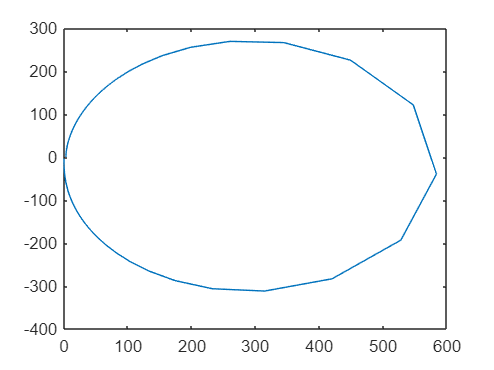


plot(real(Z), imag(Z))


% Beispiel b

Z = R1+1./(1j.*w*C1+1./(j.*w*L1))

Z =     5.00000000000000e+000 + 18.8495693162598e-003i    5.00000000000000e+000 + 207.362945031053e-003i    5.00000000000000e+000 + 395.964761662197e-003i    5.00000000000000e+000 + 584.735548109739e-003i    5.00000000000000e+000 + 773.756073784907e-003i    5.00000000000000e+000 + 963.107464059208e-003i    5.00000000000000e+000 + 1.15287131678038e+000i    5.00000000000000e+000 + 1.34312982020804e+000i    5.00000000000000e+000 + 1.53396587272918e+000i    5.00000000000000e+000 + 1.72546320472292e+000i    5.00000000000000e+000 + 1.91770650295507e+000i    5.00000000000000e+000 + 2.11078153789634e+000i    5.00000000000000e+000 + 2.30477529437356e+000i    5.00000000000000e+000 + 2.49977610598072e+000i    5.00000000000000e+000 + 2.69587379369707e+000i    5.00000000000000e+000 + 2.89315980918213e+000i    5.00000000000000e+000 + 3.09172738324308e+000i    5.00000000000000e+000 + 3.29167167999837e+000i    5.00000000000000e+000 + 3.49308995729350e+000i    5.00000000000000e+000 + 3.69608173396008e+

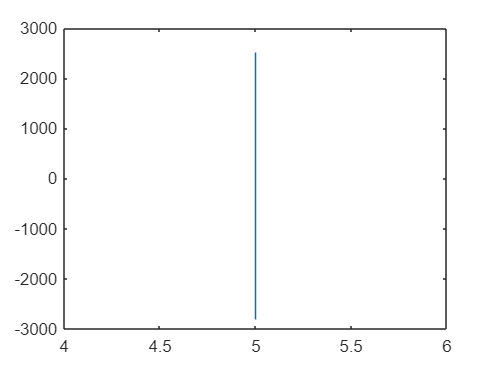

plot(real(Z), imag(Z))

## Aufgabe B10

clear 
format longeng

f = 50; R = 0.13; L=0.57e-3; C = 270e-9; w=2*pi()*f;

gamma = sqrt( (R+1j*w*L) * (1j*w*C) )

gamma =     1.33802117563057e-003 + 4.12063366968144e-003i


alpha = real(gamma); 20*log10(alpha), log(alpha)

ans =    -57.4707402666892e+000


ans =    -6.61656349107056e+000


beta = imag(gamma); beta*180/pi()

ans =     236.094918192251e-003



Zw = sqrt ( (R+1j*w*L) / (1j*w*C) )

Zw =     48.5792012741258e+000 - 15.7742728935730e+000i


abs(Zw)

ans =     51.0760852234481e+000



v = w/imag(gamma)

v =     76.2405228279529e+003


lamba = 2*pi()/imag(gamma)

lamba =     1.52481045655906e+003


b =     4.12063366968144e-003
